rng(100,"twister");
omap3D =  occupancyMap3D(0.1);
mapWidth = 1000;
mapLength = 1000;
numberOfObstacles = 1;

width = 190;                 % The largest integer in the sample intervals for obtaining width, length and height                                                     
length = 20;                % can be changed as necessary to create different occupancy maps.
height = 200;

tic
posx = [200, 200, 600, 600] ;
posy = [250, 750, 250, 750;];

for j = 1:4
    xpos1 = posx(1,j);
    ypos1 = posy(1,j);
    
    [xObstacle,yObstacle,zObstacle] = meshgrid(xpos1:xpos1+width,ypos1:ypos1+length,0:height);
    xyzObstacles = [xObstacle(:) yObstacle(:) zObstacle(:)];
    setOccupancy(omap3D,xyzObstacles,1);
end
toc

Elapsed time is 58.736081 seconds.



tic
[xGround,yGround,zGround] = meshgrid(0:mapWidth,0:mapLength,-1);
xyzGround = [xGround(:) yGround(:) zGround(:)];
setOccupancy(omap3D,xyzGround,1)
toc

Elapsed time is 17.789302 seconds.


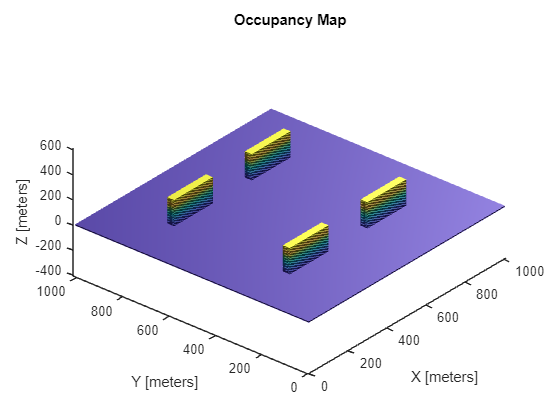

tic
figure("Name","3D Occupancy Map")
show(omap3D)

toc

Elapsed time is 0.127439 seconds.



filePath = fullfile(pwd, "guidance/testing_map.mat" )

filePath = "C:\Users\micha\MATLAB\Projects\DSE\Detailed design phase\guidance\testing_map.mat"

%exportmat = occupancyMatrix(omap3D)
save(filePath, "omap3D")
